# Exam January 11, 2019

## Exercise 1

clear
% q = sym('q',[1 4])
% syms d1 real
% syms a4 real
% syms L real
% dh = [ pi/2 0 d1 q(1);
%        pi/2 0 0 q(2);
%        pi/2 0 q(3) pi;
%        0 a4 0 q(4)]
% % 
% [T, Tpartial] = getTransformationMatrix(dh,'alpha')
% 
% for inm=1:4
% Tpartial{inm}
% end
% %Efficient Computation 4p(p)
% phomvector=[0,0,0,1]';
% n_p=[];
% for inm=[4:-1:1]
%     phomvector=simplify(Tpartial{inm}*phomvector);%optimal way to compute the P vector, uncoment this
%     n_p=phomvector;
% end
% 
% P = T(1:3,4)

% q0 = [0  pi/2 L 0]
% P4_0 = subs(P,q,q0)

% close all
% % Lengths just to test
% len = 20
% len1 = 10
% % De Luca's approach
% links = [
%     Revolute('a', 0, 'alpha', pi/2 ,'d', len1);
%     Revolute('a', 0, 'alpha',pi/2 ,'d', 0);
%     Prismatic('qlim', [0 len1],'alpha',pi/2,'theta',pi);
%      Revolute('a', len1, 'alpha', 0 ,'d', 0);
%     ];
% 
% c600 = SerialLink(links);
% c600.teach([0  pi/2 10 0],'view','x');
% c600.plot([0  pi/2 20 0],'view','x')

% % My original approach --> Not the same result
% % close all
% % len = 20
% % len1 = 10
% % links = [
% %     Revolute('a', 0, 'alpha', pi/2 ,'d', len1);
% %     Revolute('a', 0, 'alpha', -pi/2 ,'d', 0);
% %     Prismatic('qlim', [0 len],'alpha',pi/2,'theta',0);
% %     Revolute('a', len1, 'alpha', 0 ,'d', 0);
% %     ];
% 
% c600 = SerialLink(links);
 c600.teach([0,pi/2,len1,0],'view','x')
%%c600.plot([0  pi/2 10 0],'view','x')

## Exercise 2

% [Jp Jo] = getJacobian(dh,'RRPR','alpha')
% % 
% % % JpD=jacobian(n_p(1:3,:),q)
% % 
%  rank(Jo)
% % %The generic rank of the lower Jac matrix is 2
%  J = [Jp;Jo];
%  [V,W] = generalkinematics(J,P,1,q')
%   J0 = subs(J,q,q0)
%  % Jp0 = subs(Jp,q,q0)
%  q_=q0';
%  V0=subs(V,q',q_)
%  W0=subs(W,q',q_)
%  V_=[0,0,0]';
%  W_=[0,0,0]';

% % % qd = sym('qd',[4,1]);
% % % JpQd = Jp0*qd
%  qdv_= solve(V0 == V_);
% % 
%  [qdvvalues_,qdvnames_]=solvetoarray(qdv_)
% % 
%  qdw_= solve(W0 == W_);
%  [qdwvalues_,qdwnames_]=solvetoarray(qdw_)
% % 
% % % for im=1:size(qd_)

%  v1 = [1 0 1];
% w1 = [0 0 -2];
% V_ = [v1  w1]
% 
% qdv2_= solve(V0 == v1.')
% [qdv2_values_,qdv2_names_]=solvetoarray(qdv2_)
% % null(JpQdot-v1)
% %It is not possible to satisfy both v and w conditions
% [qdot1 qdot2 qdot3 qdot4] = solve([V;W] == V_)

% J0.'
% 

% Fc=null(J0.')
% tau = J0.'*Fc

## Exercise 3

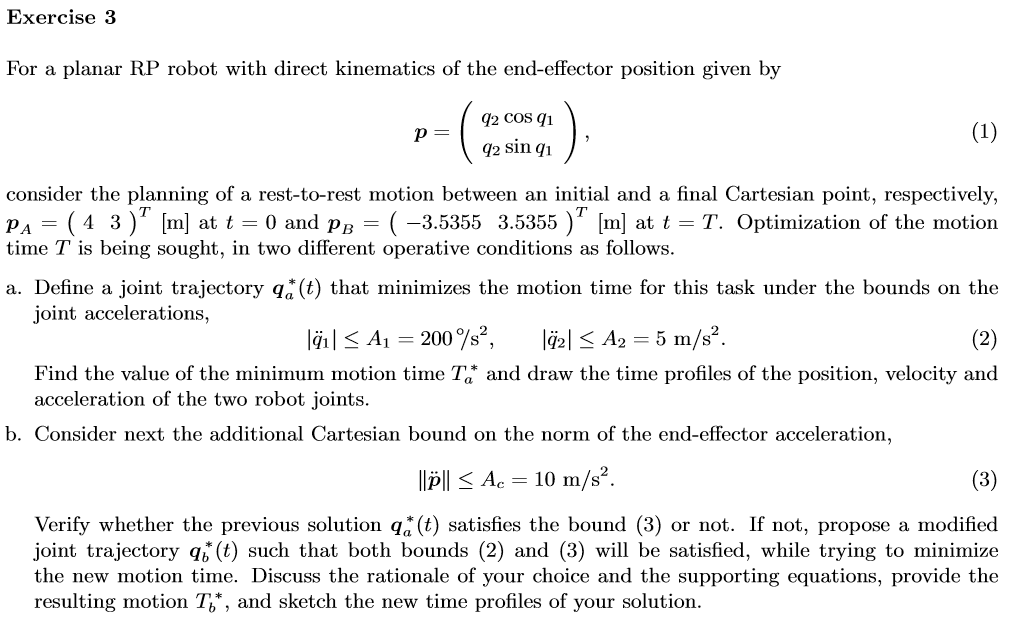

q = sym('q',[2,1])

$$q = \left(\begin{array}{c} q_{1}\\ q_{2} \end{array}\right)$$


A1_deg=200

A1_deg = 200

A1_=200*pi/180

A1_ = 3.4907

p = [q(2)*cos(q(1)); q(2)*sin(q(1))]

$$p = \left(\begin{array}{c} q_{2}\,\cos\left(q_{1}\right)\\ q_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

pa = [4;3];
pb = [-3.5355 ;3.5355];

[q_a1 q_a2 ] = solve(p == pa, q)

$$q\_a1 = \left(\begin{array}{c} -2\,\mathrm{atan}\left(3\right)\\ 2\,\mathrm{atan}\left(\frac{1}{3}\right) \end{array}\right)$$

$$q\_a2 = \left(\begin{array}{c} -5\\ 5 \end{array}\right)$$

q_Aall=eval([180/pi*q_a1 q_a2 ]);
% q_A=q_Aall(2,:)

[q_b1 q_b2 ] = solve(p == pb, q)

$$q\_b1 = \left(\begin{array}{c} -\frac{\pi }{4}\\ \frac{3\,\pi }{4} \end{array}\right)$$

$$q\_b2 = \left(\begin{array}{c} -\frac{7071\,\sqrt{2}}{2000}\\ \frac{7071\,\sqrt{2}}{2000} \end{array}\right)$$

q_Ball=eval([180/pi*q_b1 q_b2 ]);
% q_B=q_Ball(2,:)

%We choose the solution with positive q2
pick = 2;
qA_ = eval([q_a1(pick); q_a2(pick)]);
qA_deg=qA_*180/pi

qA_deg =    36.8699
  286.4789


qB_ = eval([q_b1(pick); q_b2(pick)]);
qB_deg=qB_*180/pi

qB_deg =   135.0000
  286.4762


### Bang-bang profile

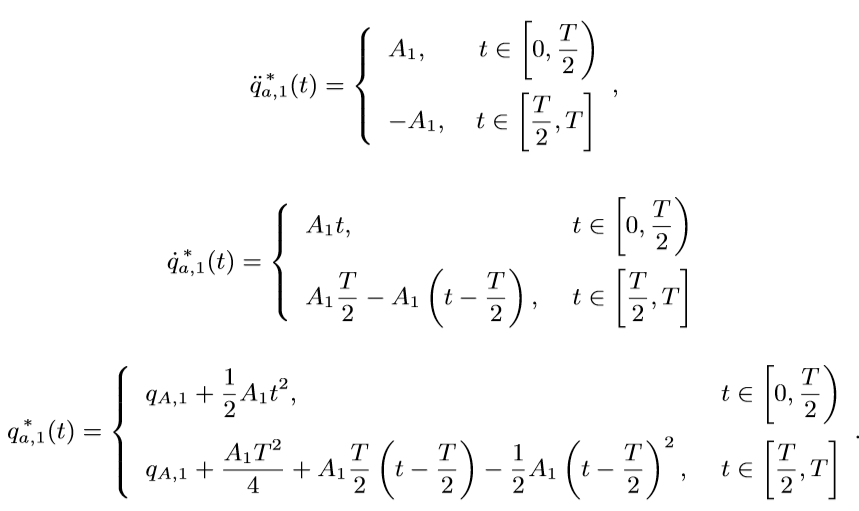

syms A1 T t t2nd
qppa1 = piecewise(0<=t<T/2, A1)

$$qppa1 = \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t \end{array}\right.$$

qppa2 = piecewise((T/2)<=t<T , -A1)

$$qppa2 = \left\{ \begin{array}{cl} -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.$$

qppa = piecewise(0<=t<T/2, A1,qppa2)

$$qppa = \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.$$

%LUCA APROACH pl=simplify(((A1*(T^2)/4)+(A1*(T/2)*(t-T/2))-((A1/2)*((t-T/2)^2))))

qa1_all = sym(zeros(3,2));

% Define initial values
qa1_all(1,1) = A1;
qa1_all(1,2) = -A1;
for i = 2:3 % 1 not included. Initial values are defined by user. A1 and A2
    for j = 1:2
        if j == 1 % First interval
            val1 = int(qa1_all(i-1,1),t); % The integral of the previous magnitude. 
            qa1_all(i,j) = val1    ;
        end
        if j == 2 % Second interval 
            val2 = subs(val1,t,T/2) ... % Value of the function in the last interval, evaluated at its final value (T/2)
                 + expand(int(qa1_all(i-1,2),t2nd)); % Integral of the function in the last unit, same interval wrt t-T/2
            qa1_all(i,j) = subs(val2,t2nd,t-T/2)    ;
        end
    end
end

%% Create piecewise functions from the calculated terms

qa_piece = sym(zeros(3,1));

for i = 1:3
    qa_piece(i,1) = piecewise(0<=t<T/2, qa1_all(i,1), ...
                            (T/2)<=t<T, qa1_all(i,2)) 
end

$$qa\_piece = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ 0\\ 0 \end{array}\right)$$

$$qa\_piece = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ A_{1}\,\left(\frac{T}{2}-t\right)+\frac{A_{1}\,T}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ 0 \end{array}\right)$$

$$qa\_piece = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ A_{1}\,\left(\frac{T}{2}-t\right)+\frac{A_{1}\,T}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ \frac{A_{1}\,T^{2}}{8}-A_{1}\,T\,\left(\frac{T}{2}-t\right)+A_{1}\,t\,\left(\frac{T}{2}-t\right) & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right. \end{array}\right)$$

%qastar = qa_piece(3)+ qA(1) % Sum initial value fo tge joint.
%t1 = subs(qastar,[t, A1],[T/2, 200])
% Have to put manually an equivalence to get the value


qa_piece(3) = vpa(qa_piece(3)+ qA_(1)*180/pi)

$$qa\_piece = \begin{array}{l} \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ A_{1}\,\left(\frac{T}{2}-t\right)+\frac{A_{1}\,T}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} 0.5\,A_{1}\,t^{2}+36.87 & \text{ if }t<0.5\,T\wedge 0\leq t\\ 0.125\,A_{1}\,T^{2}-1.0\,A_{1}\,T\,\sigma_{1}+A_{1}\,t\,\sigma_{1}+36.87 & \text{ if }t<T\wedge T\leq 2.0\,t \end{array}\right. \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.5\,T-1.0\,t \end{array}$$

%finding T
% solve(qa_piece(3) ==qB_deg(1,1),t)
digits(5)

A1_deg=A1_deg*1%to test

A1_deg = 200

%%%%%%%%%%%%%%%%%%%personal test
qa_piecetemp = vpa(subs(qa_piece,[A1],[A1_deg]))

$$qa\_piecetemp = \begin{array}{l} \left(\begin{array}{c} \left\{ \begin{array}{cl} 200.0 & \text{ if }t<0.5\,T\wedge 0\leq t\\ -200.0 & \text{ if }t<T\wedge T\leq 2.0\,t \end{array}\right.\\ \left\{ \begin{array}{cl} 200.0\,t & \text{ if }t<0.5\,T\wedge 0\leq t\\ 200.0\,T-200.0\,t & \text{ if }t<T\wedge T\leq 2.0\,t \end{array}\right.\\ \left\{ \begin{array}{cl} 100.0\,t^{2}+36.87 & \text{ if }t<0.5\,T\wedge 0\leq t\\ 200.0\,t\,\sigma_{1}-200.0\,T\,\sigma_{1}+25.0\,T^{2}+36.87 & \text{ if }t<T\wedge T\leq 2.0\,t \end{array}\right. \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.5\,T-1.0\,t \end{array}$$

solve(qa_piecetemp(3)==qB_deg(1,1),T)%didn't work check later

 
ans =
 
Empty sym: 0-by-1
 


%%%%%%%%%%%%%%%%%%%%%%%%%5
T_=sqrt(4*abs(qB_deg(1,1)-qA_deg(1,1))/A1_deg)

T_ = 1.5663

qa_piece1 = (subs(qa_piece,[A1, T],[A1_deg, T_]))

$$qa\_piece1 = \begin{array}{l} \left(\begin{array}{c} \left\{ \begin{array}{cl} 200 & \text{ if }t\in \left[0,\frac{7053926088348343}{9007199254740992}\right)\\ -200 & \text{ if }t\in \sigma_{1} \end{array}\right.\\ \left\{ \begin{array}{cl} 200\,t & \text{ if }t\in \left[0,\frac{7053926088348343}{9007199254740992}\right)\\ \frac{176348152208708575}{562949953421312}-200\,t & \text{ if }t\in \sigma_{1} \end{array}\right.\\ \left\{ \begin{array}{cl} 100.0\,t^{2}+36.87 & \text{ if }t\in \left[0,0.78314\right)\\ 313.26\,t-200\,t\,\left(1.0\,t-0.78314\right)-147.12 & \text{ if }t\in \left[0.78314,\frac{7053926088348343}{4503599627370496}\right) \end{array}\right. \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left[\frac{7053926088348343}{9007199254740992},\frac{7053926088348343}{4503599627370496}\right) \end{array}$$

vpa(qa_piece1,4)

$$ans = \left(\begin{array}{c} \left\{ \begin{array}{cl} 200.0 & \text{ if }t\in \left[0.0,0.7831\right)\\ -200.0 & \text{ if }t\in \left[0.7831,1.566\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 200.0\,t & \text{ if }t\in \left[0.0,0.7831\right)\\ 313.3-200.0\,t & \text{ if }t\in \left[0.7831,1.566\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 100.0\,t^{2}+36.87 & \text{ if }t\in \left[0.0,0.7831\right)\\ 313.3\,t-200.0\,t\,\left(1.0\,t-0.7831\right)-147.1 & \text{ if }t\in \left[0.7831,1.566\right) \end{array}\right. \end{array}\right)$$

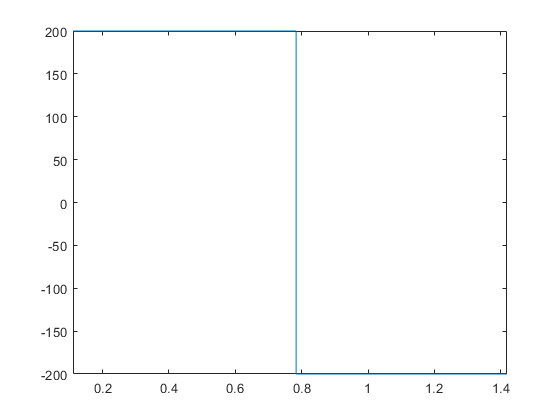

fplot(qa_piece1(1))

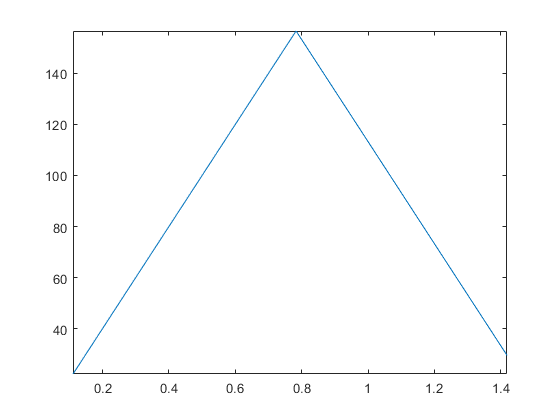

fplot(qa_piece1(2))

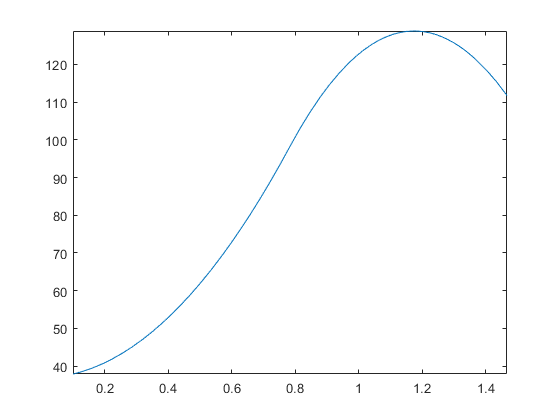

fplot(qa_piece1(3)) % There's a difference in the result.

syms q0 q1 v0 v1 t T a b c tao dq 

% Declare equation system for joint space trajectory

eq(1) = a+b+c == 1;
eq(2) = c == v0*T/dq;
eq(3) = 3*a+2*b+c == v1*T/dq;
eq.';
[as,bs,cs]=solve(eq.',[a b c])

$$as = \frac{T\,v_{0}}{\mathrm{dq}}+\frac{T\,v_{1}}{\mathrm{dq}}-2$$

$$bs = 3-\frac{T\,v_{1}}{\mathrm{dq}}-\frac{2\,T\,v_{0}}{\mathrm{dq}}$$

$$cs = \frac{T\,v_{0}}{\mathrm{dq}}$$


qd = q0 + dq*(as*tao^3 + bs*tao^2 + cs*tao)

$$qd = q_{0}+\mathrm{dq}\,\left({\mathrm{tao}}^{3}\,\left(\frac{T\,v_{0}}{\mathrm{dq}}+\frac{T\,v_{1}}{\mathrm{dq}}-2\right)-{\mathrm{tao}}^{2}\,\left(\frac{2\,T\,v_{0}}{\mathrm{dq}}+\frac{T\,v_{1}}{\mathrm{dq}}-3\right)+\frac{T\,\mathrm{tao}\,v_{0}}{\mathrm{dq}}\right)$$


qa = subs(qd,[dq tao],[q1-q0 t/T])

$$qa = q_{0}+\left(q_{0}-q_{1}\right)\,\left(\frac{t\,v_{0}}{q_{0}-q_{1}}+\frac{t^{3}\,\left(\frac{T\,v_{0}}{q_{0}-q_{1}}+\frac{T\,v_{1}}{q_{0}-q_{1}}+2\right)}{T^{3}}-\frac{t^{2}\,\left(\frac{2\,T\,v_{0}}{q_{0}-q_{1}}+\frac{T\,v_{1}}{q_{0}-q_{1}}+3\right)}{T^{2}}\right)$$

qa = subs(qa,[v0 v1],[0 0])

$$qa = q_{0}-\left(\frac{3\,t^{2}}{T^{2}}-\frac{2\,t^{3}}{T^{3}}\right)\,\left(q_{0}-q_{1}\right)$$


%Initial conditions
% w is omega, for angular velocity
% acc is angular acceleration
w = diff(qa,t)

$$w = -\left(q_{0}-q_{1}\right)\,\left(\frac{6\,t}{T^{2}}-\frac{6\,t^{2}}{T^{3}}\right)$$

acc = diff(w,t)

$$acc = \left(q_{0}-q_{1}\right)\,\left(\frac{12\,t}{T^{3}}-\frac{6}{T^{2}}\right)$$


%w0 = subs(w,t,0)
%wT = subs(w,t,T)

%acc0 = subs(acc,t,0)
%jerk = diff(acc,t)

%Evaluate the expression with the initial and final joint values
%The f subscript is used to differenciate a from the point. q_a = f

acc_f = subs(acc,[q0 q1],[qA(1) qB(1)])

Undefined function or variable 'qA'.

%Derivate to get the maximum point of accelerarion, and apply the boundary
jerk_f = diff(acc_f,t)
solve(jerk_f == 0,t)

%q0 = 